clear all
clc

## Load image, the "Lena" is used

Load and show the test image. 

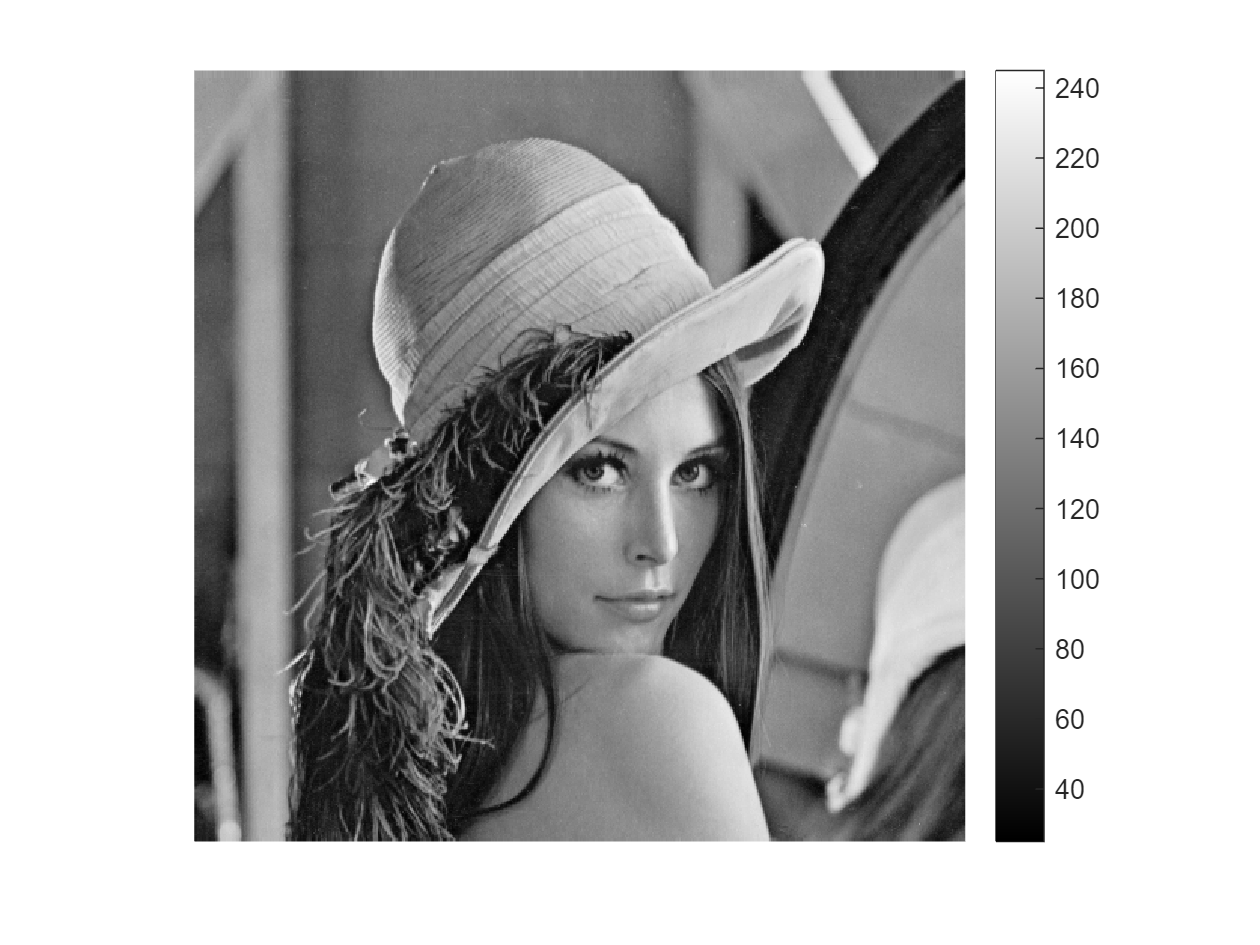

filename = 'lena_512.png';

u = double(imread(filename));
% u = u(1:2:end, 1:2:end, :); % subsampling for fast computation purpose

u0 = u;

n = size(u, 1:2);

% show the image
figure(001); clf;
imgsc(u);

## Basic setting and preparation for dictionary learning step

In this part, we provide some basic settings of the dictionary learning, including

- Dictionary atom size: p

- Number of atoms: nA

- Overlapping size: gap

- For each patch, its mean value is removed

p = [1, 1]* 9; % size of dictionary atoms
nA = prod(p); % number of Atoms

%%%% image to patches
np = prod(p); % number of pixels in each patch

%%%% number of patches
gap = 4; % control the overlapping
I = [1:gap:n(1)-p(1), n(1)-p(1)+1];
J = [1:gap:n(2)-p(2), n(2)-p(2)+1];

nP = numel(I)* numel(J); % total number of patches
lP = zeros(nP, 5); % location of each patch

%%%% extracting the patches
X = zeros(np, nP);
mP = zeros(nP, 1);

c = 1;
for j = 1:numel(J)
    range_j = J(j): J(j)+p(2) -1;
    for i=1:numel(I)
        range_i = I(i): I(i)+p(1)-1;

        lP(c, :) = [c, range_i(1), range_i(end), range_j(1), range_j(end)];

        patch = u(range_i, range_j);
        patch_ = patch(:) - 1* mean(patch(:)); % remove the DC part

        mP(c) = mean(patch(:)); % mean value of each patch is recorded for reconstruction
        X(:, c) = patch_; 

        c = c + 1;
    end
end

## Initial dictionary and coefficients

You can design other starting points strategies.

The first approach below is not working for color images

D0 = eye(np, nA) /1;
A0 = repmat(D0(:, 1:np)\ X, nA/np, 1);

The second one below works

% [D0, S, V] = svd(X); 
% A0 = S * V';

## Dictionary learning

In this part, the codes is for solving


$$\textrm{minimize}_{D, A}~\frac{1}{2} \|X-DA\|_F^2 + \lambda \|A\|_1 , \\
~~~~\textrm{subjsect to}~ \|d_i\|_2 = 1,~ i=1,..., nA
$$


here we have $D = [d_1, ..., d_{nA}]$ where $nA$ is the number of atoms. 

% regularization parameter
lambda = 50;
% a continuation technique is used for lambda, see Line 95

tol = 1e-4; 
maxits = 1e4; % maximum number of interation

**Remark** We use clean image for dictionary learning, so in principle after dictionary learning, we should have $X = D A$ hold. This mean that a very small value of $\lambda$ should be chosen. However, chooing small $\lambda$ will significantly affect the speed of the algorithm and quality of learned dictionary. Therefore, parameter continuation is used here. 

For the $256 \times 256$ image, it took me about 4 miniutes to run the following iteration with $10^4$ number of iterations. Also, note that 

000500, time: 03.96s, rel_error: 4.29e-04, obj_value: 7.98e+07...
001000, time: 07.98s, rel_error: 1.92e-04, obj_value: 5.71e+07...
001500, time: 12.06s, rel_error: 1.68e-04, obj_value: 4.13e+07...
002000, time: 15.86s, rel_error: 1.90e-04, obj_value: 3.01e+07...
002500, time: 19.63s, rel_error: 1.66e-04, obj_value: 2.22e+07...
003000, time: 23.49s, rel_error: 2.22e-04, obj_value: 1.63e+07...
003500, time: 27.32s, rel_error: 1.97e-04, obj_value: 1.20e+07...
004000, time: 31.01s, rel_error: 1.92e-04, obj_value: 8.87e+06...
004500, time: 34.71s, rel_error: 2.67e-04, obj_value: 6.25e+06...
005000, time: 38.42s, rel_error: 2.37e-04, obj_value: 4.22e+06...
005500, time: 42.25s, rel_error: 2.43e-04, obj_value: 2.93e+06...
006000, time: 46.05s, rel_error: 2.81e-04, obj_value: 1.94e+06...
006500, time: 49.98s, rel_error: 2.29e-04, obj_value: 1.41e+06...
007000, time: 53.90s, rel_error: 1.22e-04, obj_value: 1.26e+06...


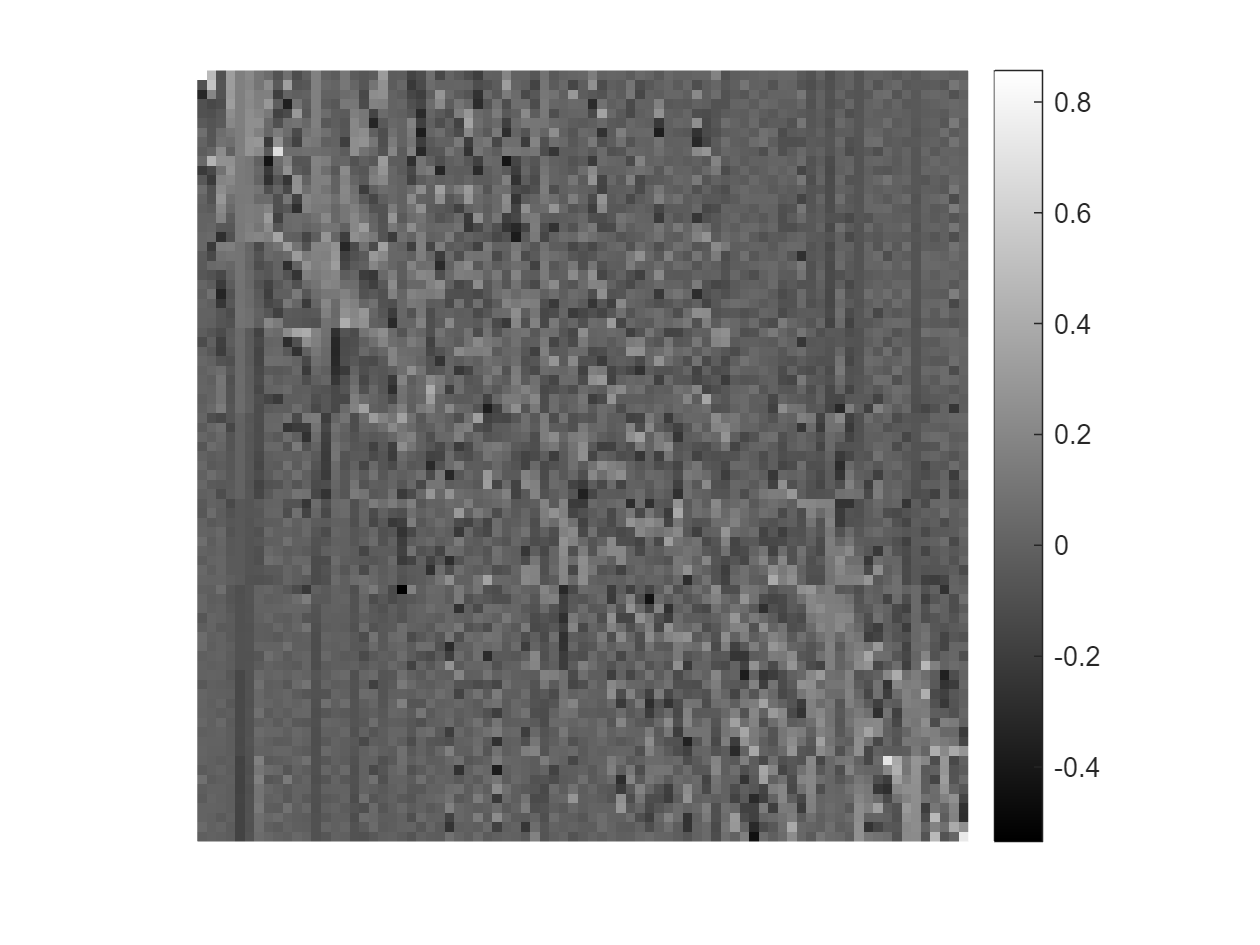

D = D0;
A = A0;

ek = zeros(maxits, 1); %% record residual error

tic;
its = 1;
while its<=maxits-1
    D_old = D;
    A_old = A;

    % gradient descent on D
    L_D = norm(A*A') + .1; % estimated Lipschitz constant
    gamma_D = 1.9/L_D; % the step-size

    grad_D = (-X + D*A)* (A'); % gradient respect to D
    D = D - (1.9/L_D)* grad_D; 

    % enforcing unit length constraint on to the atoms
    for j=1:nA
        D(:, j) = D(:, j) / norm(D(:,j));
    end

    % gradient descent on A
    L_A = norm(D*D') + .1; % estimated Lipschitz constant
    gamma_A = 1.9/L_A; % the step-size

    grad_A = (D')* (-X + D*A); % gradient respect to A
    w = A - gamma_A* grad_A;

    % this is for dealing the l1-norm, called soft-thresholding shrinkage
    A = sign(w) .* max(abs(w)-lambda*gamma_A, 0);

    ek(its) = norm(D(:)-D_old(:)) /norm(D(:));

    if mod(its, 5e2)==0; lambda = max(lambda/1.5, 1/2); end

    if ek(its) < tol || ek(its) > 1e10 
        if its>1e3-1
            break; 
        end 
    end

    if mod(its,5e2)==0
        fprintf('%06d, time: %05.2fs, rel_error: %05.2e, obj_value: %05.2e...\n',...
            its, toc, ek(its), norm(X-D*A, 'fro')^2);

        imgsc(D);
        pause(.01);
    end

    its = its + 1;
end

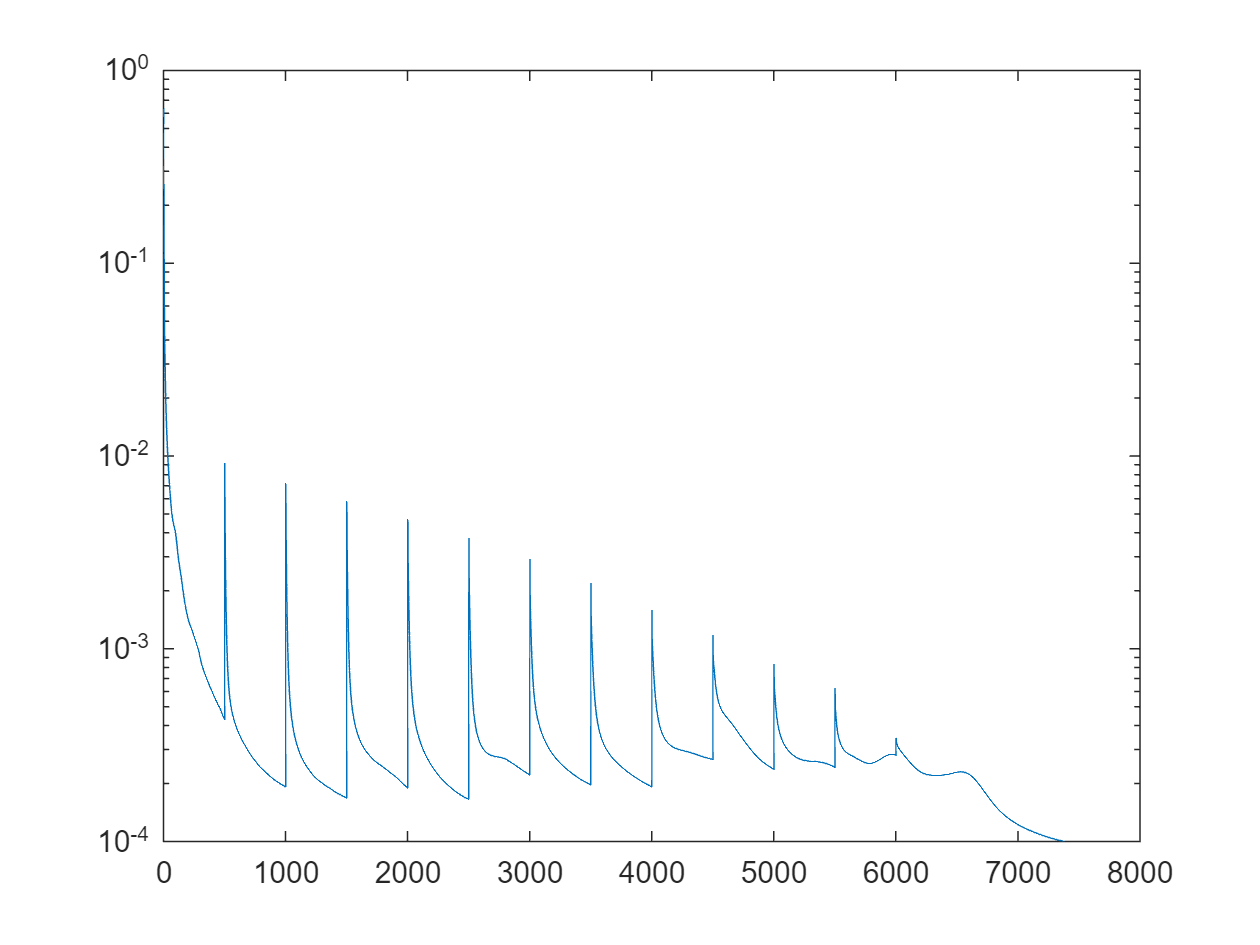


fprintf('\n');

ek = ek(1:its-1);

figure(002), clf;
semilogy(ek);

% due to parameter continuation, ek is not monotonic.

## Output the learned dictionary

Display the learning dictionary atoms.

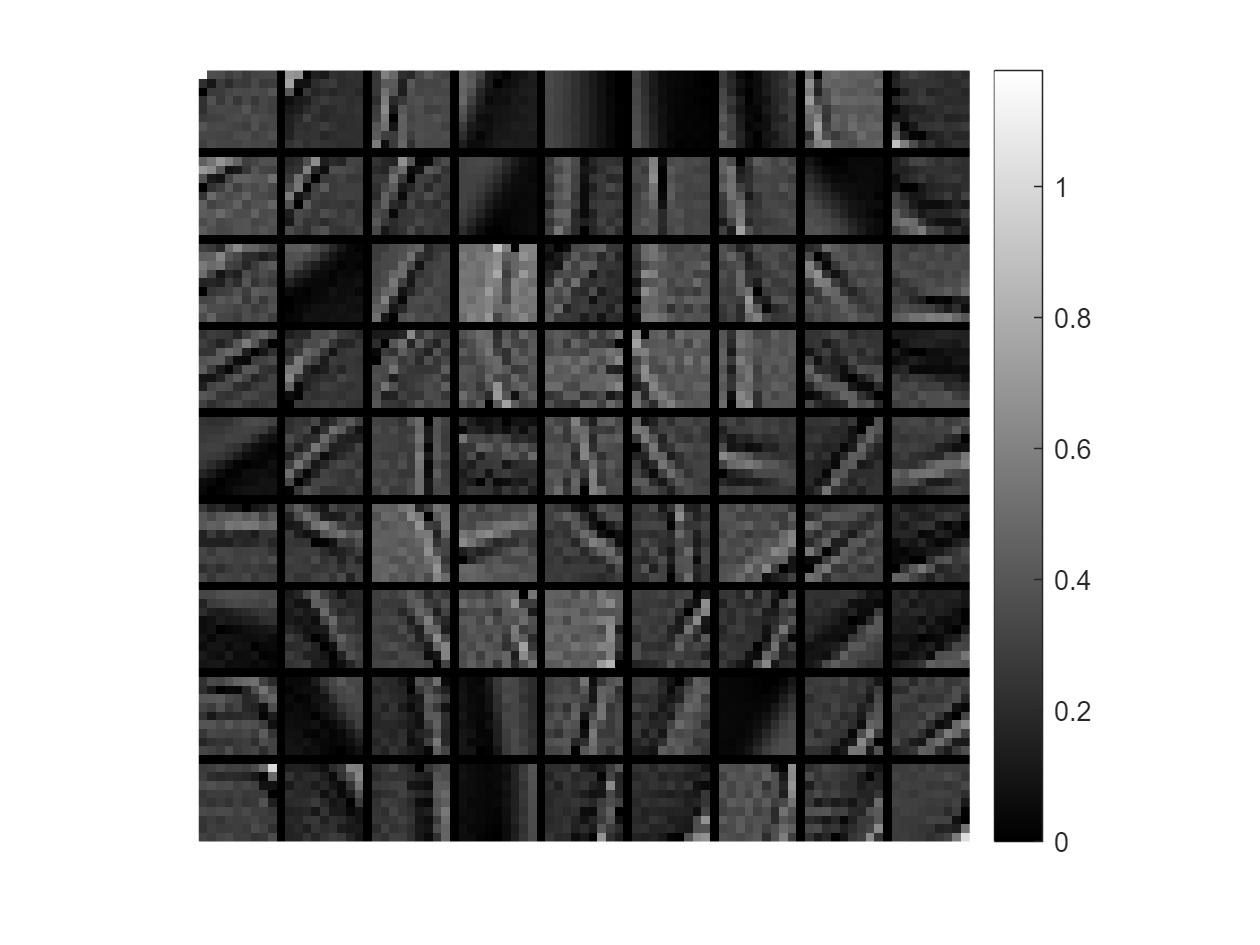

i_size = prod(p) + p(1) - 1;
imD = zeros(i_size, i_size);

c = 0;
for i=1: p(1)
    range_i = (i-1)*(p(1)+1) + 1 : i*(p(1)+1)-1;
    for j = 1: p(2)
        c = c + 1;

        range_j = (j-1)*(p(2)+1) + 1 : j*(p(2)+1)-1;

        atom = D(:, c);
        imD(range_i, range_j) = reshape(atom, p) - min(atom(:));
    end
end

figure(002); clf;
imgsc(imD);

## Comparison between the original image and the approximation $DA$

After dictionary learning, we obtain the an approximation of $X$ with $DA$, note that this approximation is accurate if $\lambda$ in the parameter continuation converges to $0$.

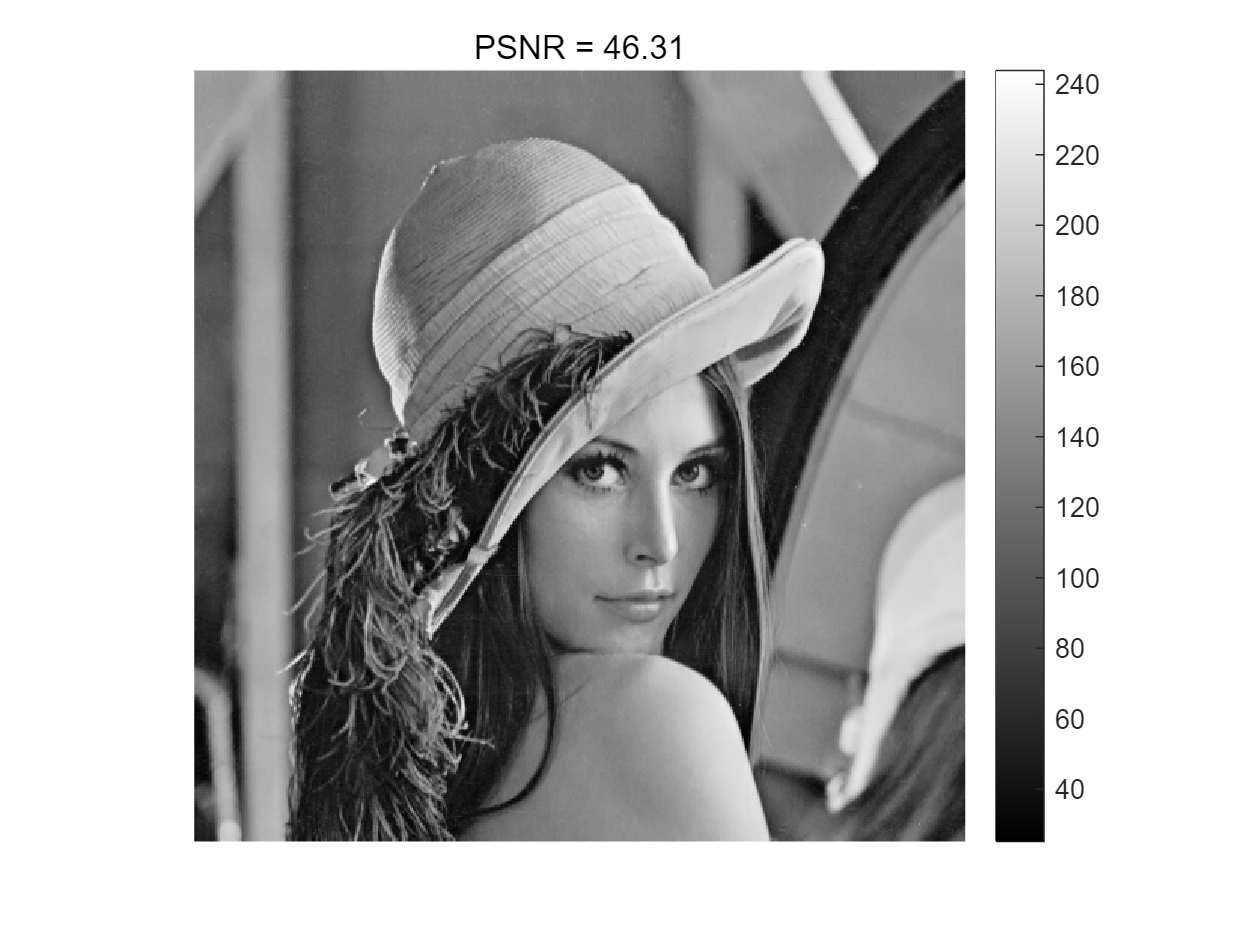

sA = wthresh(A, 'h', 3);
y = D* sA;
Y = 0* u;
W = 0* u;

for i=1:nP

    p_location = lP(i, 2:5);
    patch = y(:, i); % - mean(patch(:));

    range_i = p_location(1):p_location(2);
    range_j = p_location(3):p_location(4);

    Y(range_i, range_j) = Y(range_i, range_j) + reshape(patch, p) + mP(i);
    W(range_i, range_j) = W(range_i, range_j) + 1;
end

yy = Y./W;



figure(004), clf;
imgsc(yy);
title(sprintf('PSNR = %.2f', psnr(u, yy)));

## Image with random Gaussian noise

First step is add noise to the clean image and extrat the patches. 

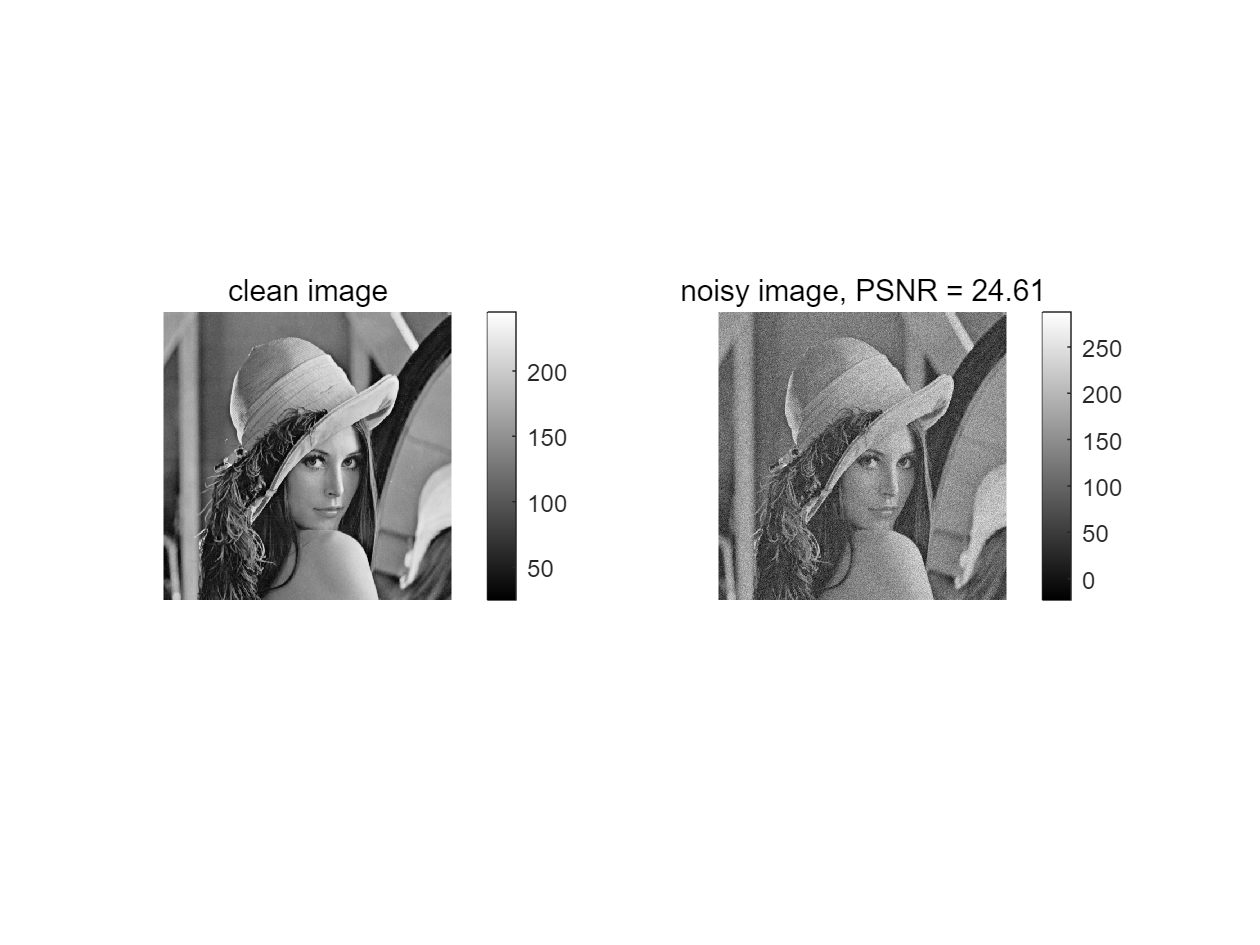

sigma = 15; % standard variance of the noise
noise = sigma* randn(size(u)); % random Gaussian noise

u_noise = u + noise; % noisy image

figure(005), clf;
subplot(121), imgsc(u), title('clean image');
subplot(122), imgsc(u_noise), title(sprintf('noisy image, PSNR = %.2f', psnr(u, u_noise)));


%%%% extract patches from noisy image
X_noise = zeros(np, nP);
mP_noise = zeros(nP, 1);

c = 1;
for j = 1:numel(J)
    range_j = J(j): J(j)+p(2) -1;
    for i=1:numel(I)
        range_i = I(i): I(i)+p(1)-1;

        lP(c, :) = [c, range_i(1), range_i(end), range_j(1), range_j(end)];

        patch = u_noise(range_i, range_j);
        patch_ = patch(:) - 1* mean(patch(:)); % remove the DC part

        mP_noise(c) = mean(patch(:)); % mean value of each patch is recorded for reconstruction
        X_noise(:, c) = patch_; % - mean(patch(:));

        c = c + 1;
    end
end

% the different in meanvalue is actually not large.
fprintf('Max difference between the values of patch mean value: %.2f...\n', max(abs(mP-mP_noise)));

Max difference between the values of patch mean value: 6.41...


## Denoising using LASSO

Now with the learned dicitonary $D$ and noisy patches $X_{\textrm{noise}}$, the goal is to find the sparse representation coefficient $C$ of $X_{\textrm{noise}}$ under $D$. To this end, we can condier the following problem


$$\textrm{minimize}_{C}~\frac{1}{2} \|X_{\textrm{noise}}-DC\|_F^2 + \mu \|C\|_1 $$


herer $C$ is the only unknown. 

mu = 100; % regularization parameter

tol = 1e-4;
maxits = 1e4;

L = norm(D)^2; % Lipschitz constant of the gradient of 0.5*||X-DC||_F^2
gamma = 1/ L;

C = A; % initialize C with A above

ek_lasso = zeros(maxits, 1);

its = 1;
while its<=maxits
    C_old = C;
    
    % gradient descent on the quadratic part
    grad = D'*(D*C - X_noise);
    w = C - gamma* grad;

    % this is for dealing the l0-norm, called hard-thresholding shrinkage
    % which is similar to OMP (orthogonal matching pursuit)
    C = wthresh(w, 'h', gamma*mu);

    res = C - C_old;
    ek_lasso(its) = norm(res, 'fro');

    %%% stopping criterion is not used here...
    if ek_lasso(its) < tol || ek_lasso(its) > 1e10 
        if its>1e1-1
            break; 
        end 
    end

    if mod(its,5e2)==0
        fprintf('%06d, rel_error: %05.2e, obj_value: %07.4e, l1_norm: %05.2e...\n',...
            its, ek_lasso(its), norm(X-D*C, 'fro')^2/2+mu*norm(C(:), 1), mu*norm(C(:), 1));
    end

    its = its + 1;
end

000500, rel_error: 1.50e+01, obj_value: 3.4124e+08, l1_norm: 3.19e+08...
001000, rel_error: 6.75e-01, obj_value: 3.4126e+08, l1_norm: 3.19e+08...
001500, rel_error: 3.03e-01, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
002000, rel_error: 7.31e-02, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
002500, rel_error: 4.03e-02, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
003000, rel_error: 2.61e-02, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
003500, rel_error: 1.77e-02, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
004000, rel_error: 1.25e-02, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
004500, rel_error: 8.96e-03, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
005000, rel_error: 6.54e-03, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
005500, rel_error: 4.81e-03, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
006000, rel_error: 3.56e-03, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
006500, rel_error: 2.65e-03, obj_value: 3.4127e+08, l1_norm: 3.19e+08...
007000, rel_error: 1.97e-03, obj_value: 3.4127e+08,

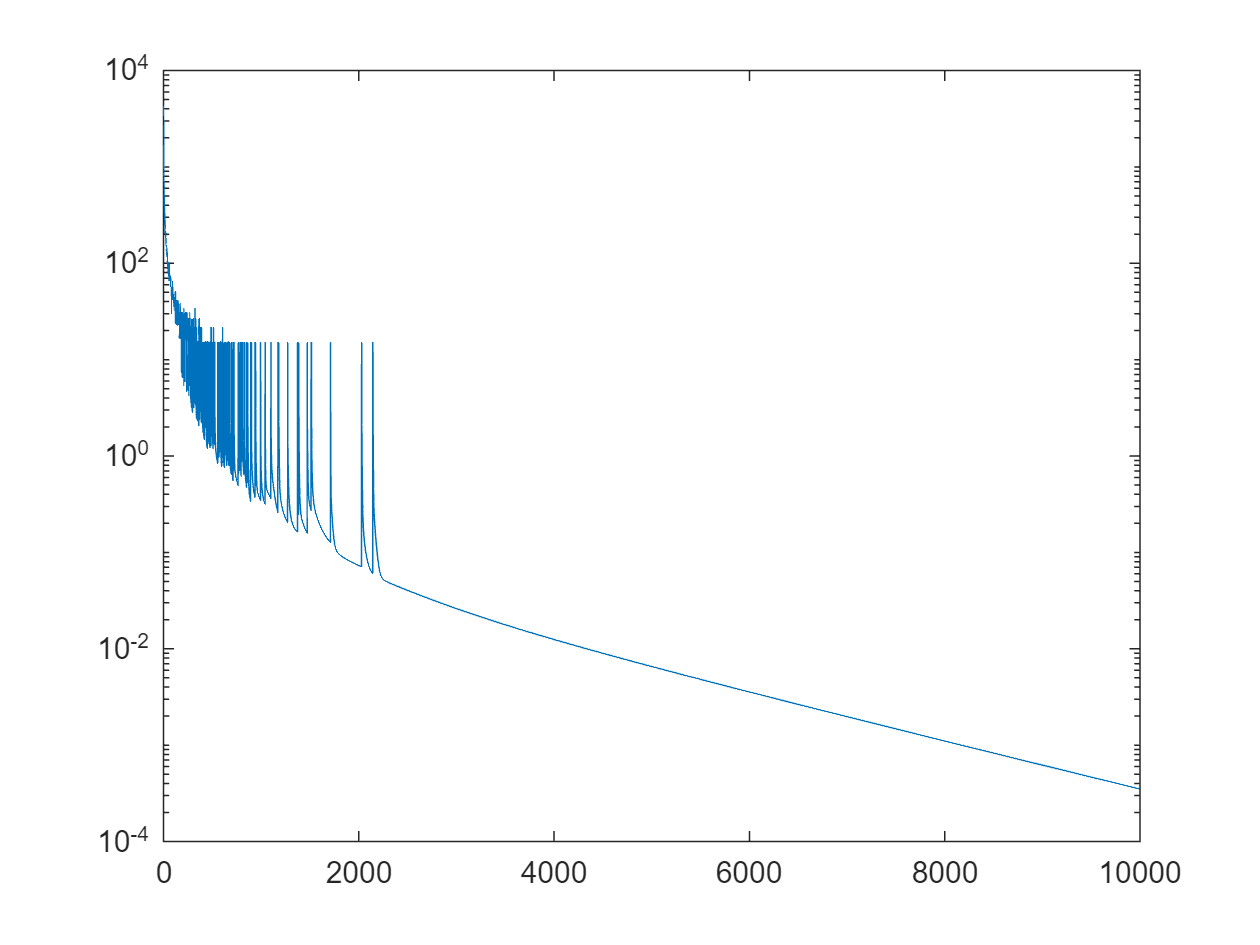


ek_lasso = ek_lasso(1:its-1);

figure(006), clf;
semilogy(ek_lasso);

## reconstruction of the denoised image

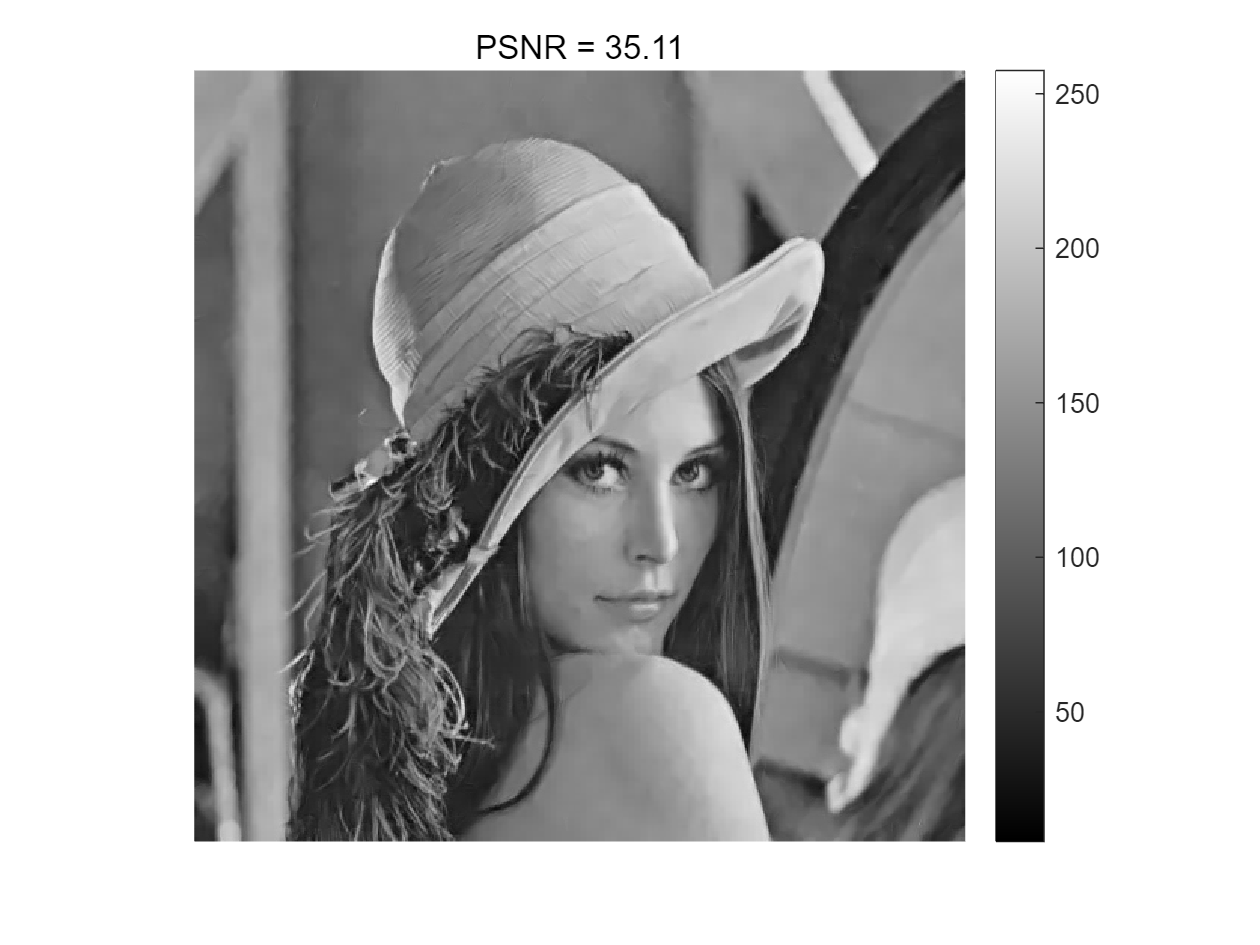


y = D* C;
Y = 0* u;
W = 0* u;

for i=1:nP
    p_location = lP(i, 2:5);
    patch = y(:, i) + mP_noise(i); % - mean(patch(:));

    range_i = p_location(1):p_location(2);
    range_j = p_location(3):p_location(4);

    Y(range_i, range_j) = Y(range_i, range_j) + reshape(patch, p);
    W(range_i, range_j) = W(range_i, range_j) + 1;
end

u_denoise = Y./W;



figure(007), clf;
imgsc(u_denoise);
title(sprintf('PSNR = %.2f', psnr(u, u_denoise)));

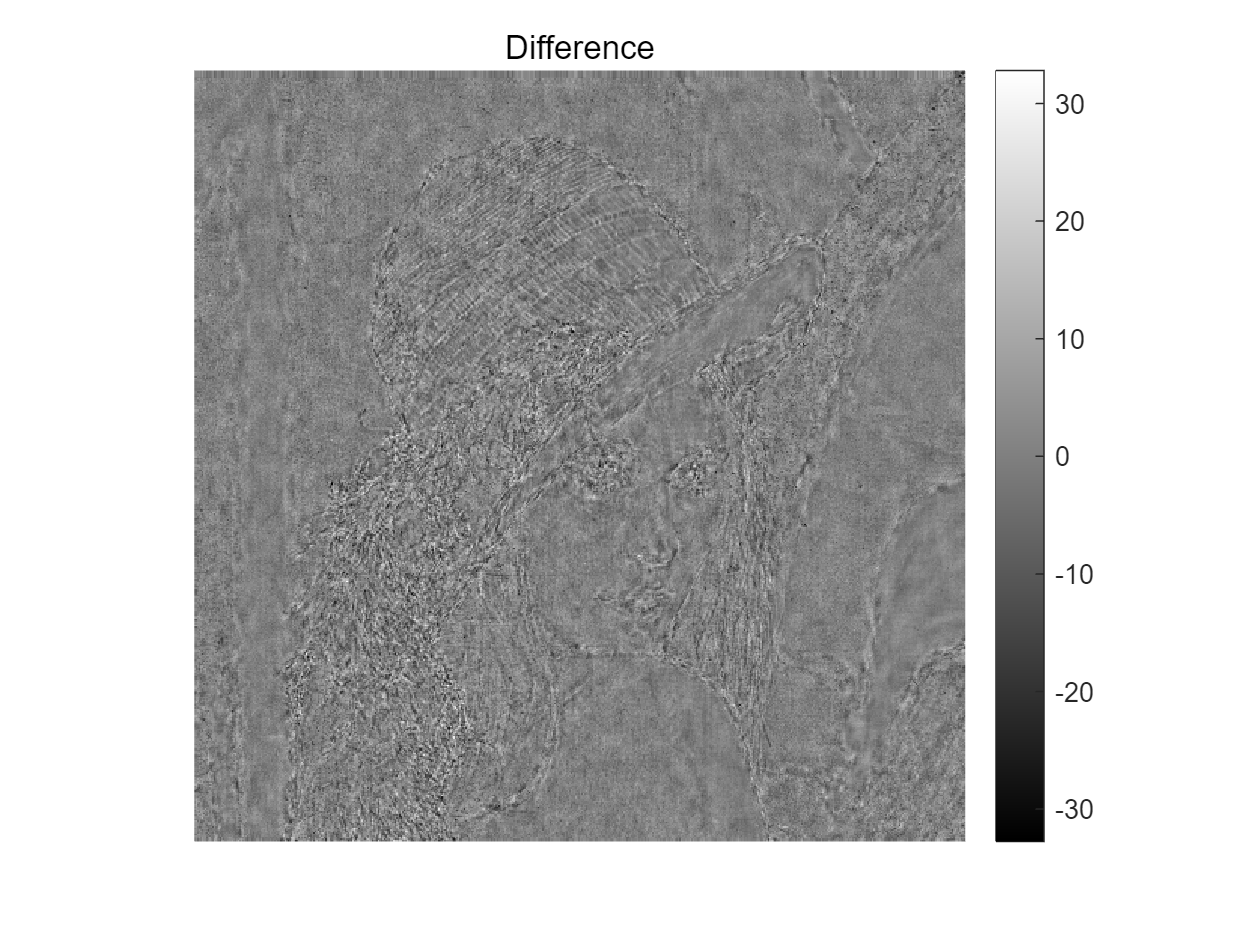


figure(008), clf;
imgsc(u_denoise - u);
title('Difference');